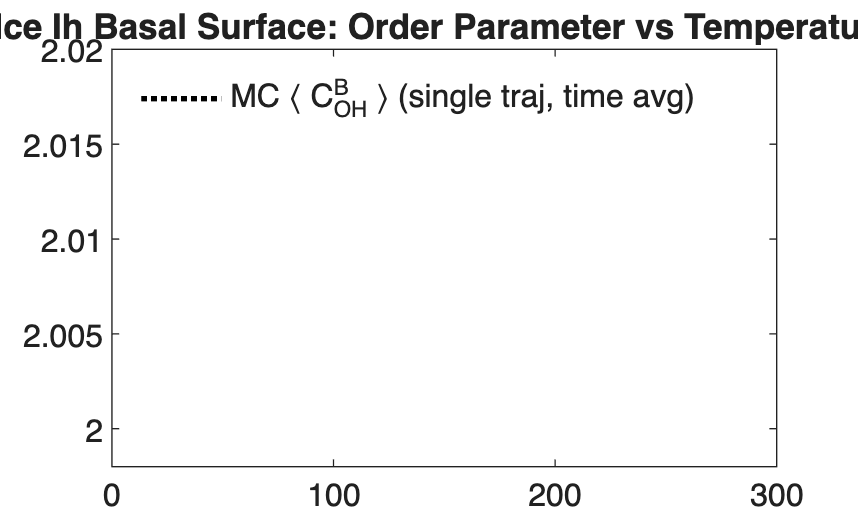

%% Ice Ih Basal Surface - <C_OH> vs T
%  Single trajectory, sequential annealing.
%  After equilibration, time average = ensemble average (ergodic theorem).
%  No need for many trajectories or large N_sample.

clear; clc; close all;

%% Parameters
Lx = 6;  Ly = 4;
N     = Lx * Ly;
N_occ = N / 2;
epsilon_meV  = 0;
kB_meV_per_K = 0.08617;

% Temperature: high -> low (sequential annealing direction)
T_list = fliplr(linspace(10, 300, 100));
n_T    = length(T_list);

% Each temperature: equilibrate briefly (config inherited), then time-average
N_equil  = 50000;   % short because we inherit the previous T config
N_sample = 1000000;   % steps for time average

%% Build neighbor list
nn_dix = [+1,-1, 0, 0,+1,-1];
nn_diy = [ 0, 0,+1,-1,-1,+1];
nn_list = zeros(N, 6, 'int32');
for iy = 1:Ly
    for ix = 1:Lx
        idx = (iy-1)*Lx + ix;
        for k = 1:6
            nx = mod(ix-1+nn_dix(k), Lx) + 1;
            ny = mod(iy-1+nn_diy(k), Ly) + 1;
            nn_list(idx,k) = int32((ny-1)*Lx + nx);
        end
    end
end

%% Initialize: stripe phase ground state (C_OH = 2, energy minimum)
occ = false(N, 1);
for iy = 1:Ly
    if mod(iy,2) == 1
        for ix = 1:Lx
            occ((iy-1)*Lx+ix) = true;
        end
    end
end
occ_idx  = int32(find(occ));
free_idx = int32(find(~occ));

%% Main loop: single trajectory across all temperatures
COH_mean = zeros(1, n_T);

for iT = 1:n_T
    T    = T_list(iT);
    beta = 1.0 / (kB_meV_per_K * T);

    %--- Equilibration (config directly inherited from previous temperature)
    for step = 1:N_equil
        [occ, occ_idx, free_idx] = mc_swap( ...
            occ, occ_idx, free_idx, nn_list, N_occ, beta, epsilon_meV);
    end

    %--- Time average (this IS the ensemble average by ergodic theorem)
    COH_sum = 0.0;
    for step = 1:N_sample
        [occ, occ_idx, free_idx] = mc_swap( ...
            occ, occ_idx, free_idx, nn_list, N_occ, beta, epsilon_meV);
        occ_rows = nn_list(occ, :);
        COH_sum  = COH_sum + double(sum(occ(occ_rows(:)))) / N_occ;
    end
    COH_mean(iT) = COH_sum / N_sample;
end

% Restore low -> high order for plotting
T_plot   = fliplr(T_list);
COH_plot = fliplr(COH_mean);

%% Wannier analytic approximation
T_cont      = linspace(1, 320, 800);
x           = epsilon_meV ./ (kB_meV_per_K * T_cont);

%% Plot
figure('Color','white','Position',[100 100 850 520]);

plot(T_plot, COH_plot,   'k:',  'LineWidth', 2.0, ...
    'DisplayName','MC \langle C_{OH}^B \rangle (single traj, time avg)');

title('Ice Ih Basal Surface: Order Parameter vs Temperature', ...
    'FontSize',14,'FontWeight','bold');
legend('Location','northwest','FontSize',12,'Box','off');
xlim([0 300]); ylim([1.998 3]);
grid off; box on; set(gca,'FontSize',12);


%% Local functions
function [occ, occ_idx, free_idx] = mc_swap( ...
        occ, occ_idx, free_idx, nn_list, N_occ, beta, epsilon)
    i_pos = randi(N_occ);
    j_pos = randi(N_occ);
    i = occ_idx(i_pos);
    j = free_idx(j_pos);
    c_i = sum(occ(nn_list(i,:)));
    c_j = sum(occ(nn_list(j,:)));
    if any(nn_list(i,:) == j)
        delta_E = epsilon * double(c_j - 1 - c_i);
    else
        delta_E = epsilon * double(c_j - c_i);
    end
    if delta_E <= 0 || rand() < exp(-beta * delta_E)
        occ(i) = false;  occ(j) = true;
        occ_idx(i_pos) = j;  free_idx(j_pos) = i;
    end
end